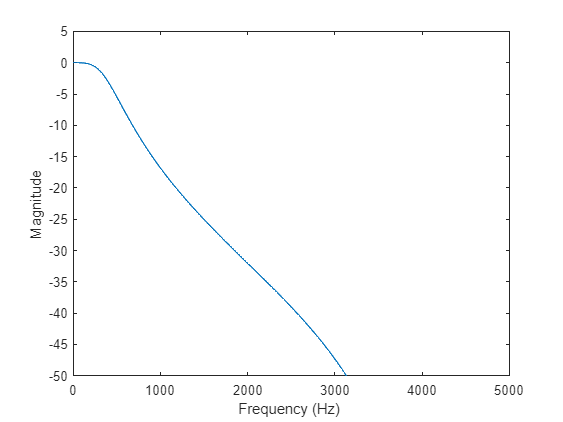

fs=8000; % sampling rate for discrete signal
[b, a]=butter(2,400/(fs/2));
[h,f]=freqz(b,a,512,fs); % Digital filter frequency response
figure(1)
plot(f,20*log10(abs(h))); % in dB scale
axis([0 5000 -50 5]);
xlabel('Frequency (Hz) ');
ylabel('Magnitude');

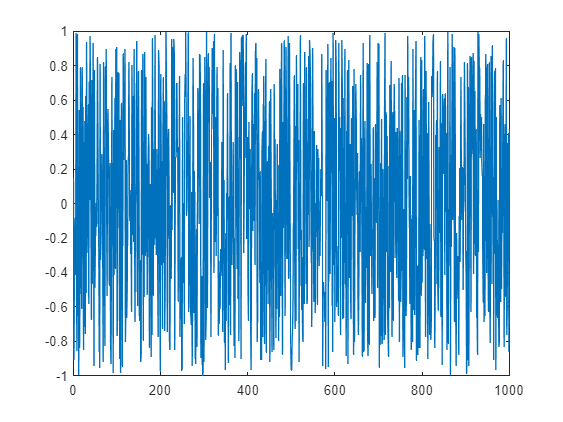

N=1000; 
noise = 1-2*rand(1,N);
figure(2)
plot(1:N, noise)


% [Pxx,w] =psd(sig,512,fs); 